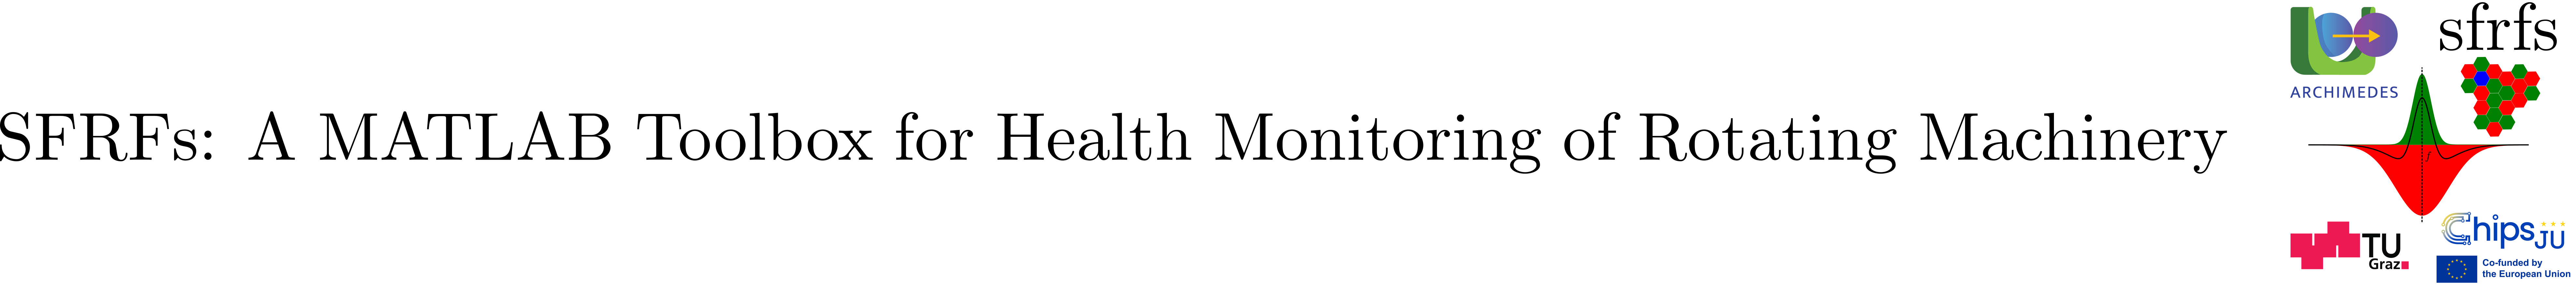

# OpponentBandsSchema

## Summary

`OpponentBandsSchema` provides constant field names for representing a center-surround opponent frequency band pair.

## Description

This schema standardizes how center and surround frequency intervals are represented when defining opponent band pairs, typically used to parameterize center-surround receptive fields.

Each opponent band is encoded as a pair of frequency bounds `[fLow, fHigh]` in Hz, distinguishing:

- an excitatory (center) band, and

- an inhibitory (surround) band.

By centralizing these field names, the schema avoids ad hoc conventions and ensures consistent interpretation of opponent band definitions across the toolbox.

### Defined fields

### Notes

- This schema defines **frequency interval pairs**, not gain masks or spectral weights.

- It is typically consumed by mask-generation and receptive-field construction stages.

- It is independent of how these bands are later mapped to gain functions or responses.

### See also

[`structs.FrequencyBankMasksSchema`](matlab:open('./FrequencyBankMasksSchema.mlx'))`, `[`dicts.BandMapSchema`](matlab:open('./BandMapSchema.mlx'))`, `[`ReceptiveFieldGainFunctions`](matlab:open('./ReceptiveFieldGainFunctions.mlx'))`, `[`FaultFrequencyBands`](matlab:open('./FaultFrequencyBands.mlx'))`, `[`BearingFrequencyBands`](matlab:open('./BearingFrequencyBands.mlx'))

## Example

import structs.OpponentBandsSchema

bands = struct();

% Setting (write)
bands.(OpponentBandsSchema.CENTER)   = [95, 105];
bands.(OpponentBandsSchema.SURROUND) = [90, 110];

% Getting (read)
C = bands.(OpponentBandsSchema.CENTER);
S = bands.(OpponentBandsSchema.SURROUND);

disp("Center band: " + mat2str(C));

Center band: [95 105]


disp("Surround band: " + mat2str(S));

Surround band: [90 110]


## API documentation

### MATLAB help

help OpponentBandsSchema

  OpponentBandsSchema  Field name constants for opponent frequency bands

    Documentation for structs.OpponentBandsSchema



## Source code

The source of the class can be found in [`OpponentBandsSchema`](matlab:open('../../+structs/OpponentBandsSchema.m')).

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).